# Direct Dynamic Simulation

## Related Slides:

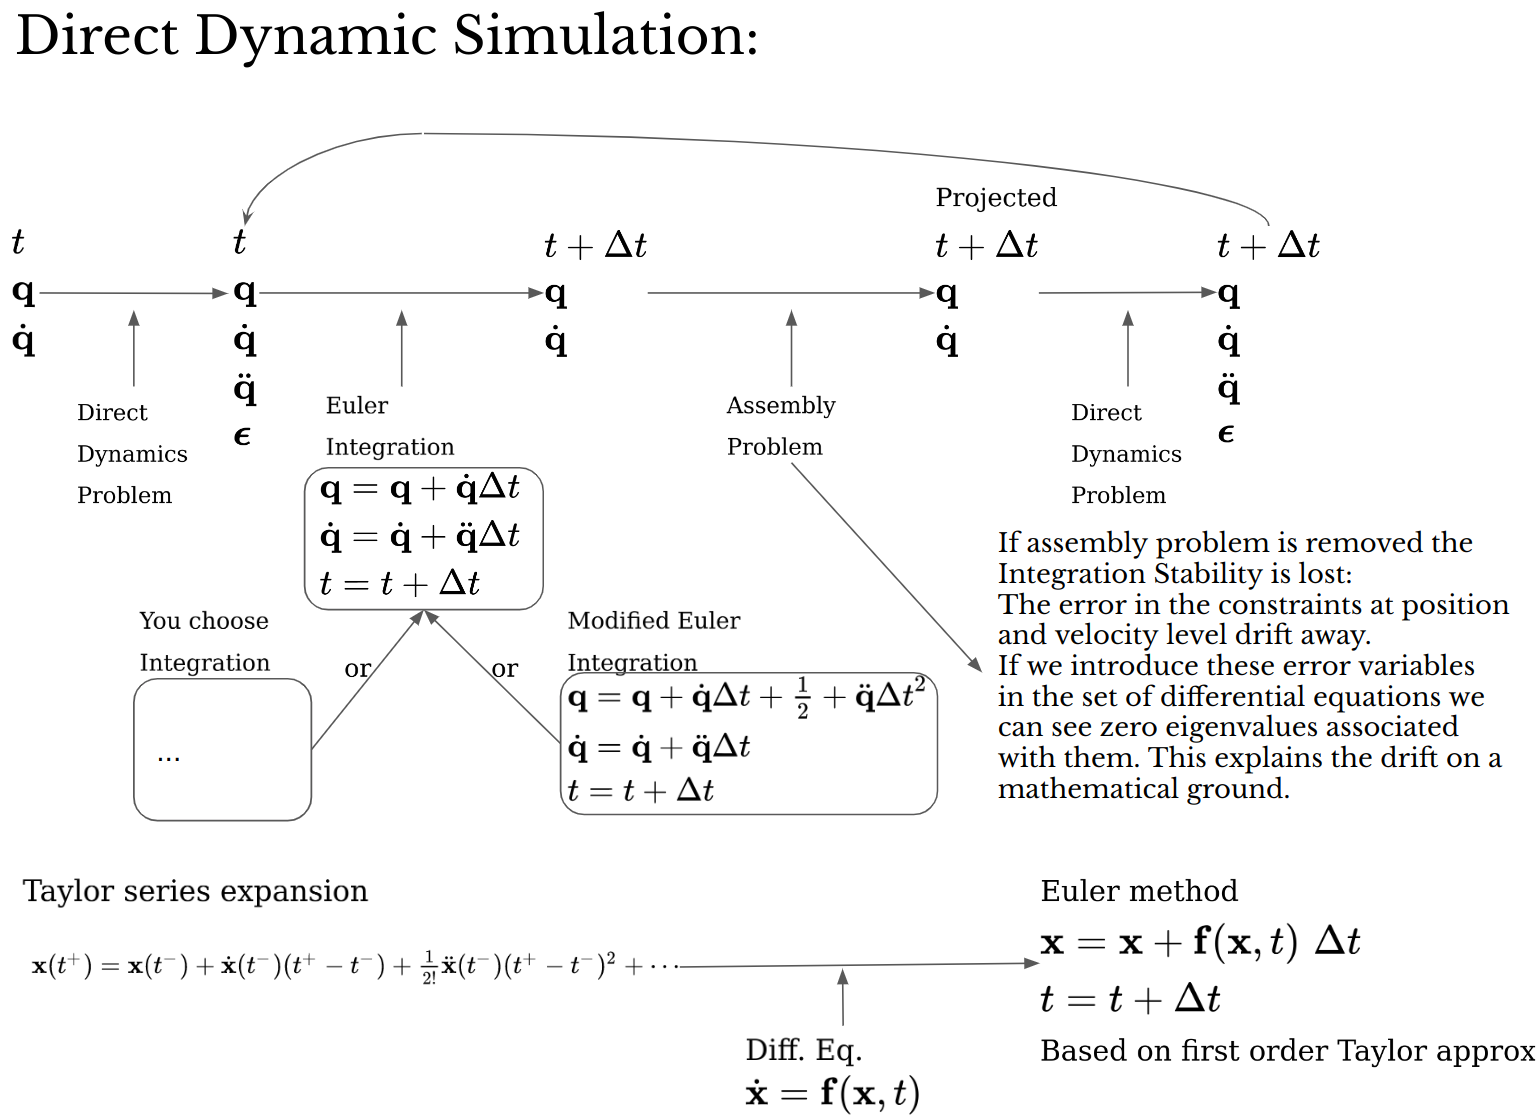

function dynamic_simulation(fid,integrator_name,options)
global t_value t_refresh t_end Delta_t Delta_t_refresh q_value dq_value ddq_value n_q
global integrator_type matlab_ode_suite_options

if nargin==1
    integrator_name=integrator_type;
elseif nargin<3
    options = matlab_ode_suite_options;
end

t_refresh=t_value;

**If integrator is Euler**

if strcmp(integrator_name,'Euler')
    while t_value <=t_end

Modified Euler integration

        q_value=q_value+Delta_t*(dq_value+0.5*Delta_t*ddq_value);
        dq_value=dq_value+Delta_t*ddq_value;

        t_value=t_value+Delta_t;

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with a Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid);
    end

**If integrator is Runge-Kutta 4**

elseif strcmp(integrator_name,'RK4')
    while t_value <=t_end

RK4 integration

        t_value_0=t_value;
        q_value_0=q_value;
        dq_value_0=dq_value;

        % Computing k1
        q_k1=Delta_t*dq_value;
        dq_k1=Delta_t*ddq_value;

        % Computing k2
        t_value=t_value_0+Delta_t/2;
        q_value=q_value_0+q_k1/2;
        dq_value=dq_value_0+dq_k1/2;

        direct_dynamics_problem;

        q_k2=Delta_t*dq_value;
        dq_k2=Delta_t*ddq_value;

        % Computing k3
        t_value=t_value_0+Delta_t/2;
        q_value=q_value_0+q_k2/2;
        dq_value=dq_value_0+dq_k2/2;

        direct_dynamics_problem;

        q_k3=Delta_t*dq_value;
        dq_k3=Delta_t*ddq_value;

        % Computing k4
        t_value=t_value_0+Delta_t;
        q_value=q_value_0+q_k3;
        dq_value=dq_value_0+dq_k3;

        q_k4=Delta_t*dq_value;
        dq_k4=Delta_t*ddq_value;

        % Position Actualization
        q_value=q_value_0+1/6*(q_k1+2*q_k2+2*q_k3+q_k4);

        % Velocity Actualization
        dq_value=dq_value_0+1/6*(dq_k1+2*dq_k2+2*dq_k3+dq_k4);

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with a Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid);
    end

**If integrator is MATLAB's ODE45**

elseif strcmp(integrator_name,'ode45')
    while t_value <=t_end
        [t,x] = ode45(@d_q_dq_,[t_value,t_value+Delta_t],[q_value;dq_value],options);
        t_value=t(end);
        q_value=x(end,1:n_q)';
        dq_value=x(end,n_q+1:end)';

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid(1));
        if length(fid)==2
            printf_data(fid(2),@data_);
        end
    end

**If integrator is MATLAB's ODE23**

elseif strcmp(integrator_name,'ode23')
    while t_value <=t_end
        [t,x] = ode23(@d_q_dq_,[t_value,t_value+Delta_t],[q_value;dq_value],options);
        t_value=t(end);
        q_value=x(end,1:n_q)';
        dq_value=x(end,n_q+1:end)';

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with a Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid);
    end

**If integrator is MATLAB's ODE23s**

elseif strcmp(integrator_name,'ode23s')
    while t_value <=t_end
        [t,x] = ode23s(@d_q_dq_,[t_value,t_value+Delta_t],[q_value;dq_value],options);
        t_value=t(end);
        q_value=x(end,1:n_q)';
        dq_value=x(end,n_q+1:end)';

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with a Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid);
    end

**If integrator is MATLAB's ODE23t**

elseif strcmp(integrator_name,'ode23t')
    while t_value <=t_end
        [t,x] = ode23t(@d_q_dq_,[t_value,t_value+Delta_t],[q_value;dq_value],options);
        t_value=t(end);
        q_value=x(end,1:n_q)';
        dq_value=x(end,n_q+1:end)';

Constraint projection @ Position and Velocity level

        solveConstraintProjectionPosVel;

Direct Dynamics

        solveDirectDynamicsProblem;

Update Drawing with a Delta_t_refresh period

        if t_value-t_refresh > Delta_t_refresh
            updateDraws;
            t_refresh=t_refresh+Delta_t_refresh;
        end

Write Extended State

        printf_extended_state(fid);
    end
else
    error('integrator not defined');
end

end